%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 121893*0.946

W = 1.1531e+05


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1303; %ft^2
AR = 10.68

AR = 10.6800

AR2 = 5.23

AR2 = 5.2300

b2=100

b2 = 100

TaperRatio = 0.6;
b = sqrt(AR*S)

b = 117.9663

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.97;
K = 1/(e*pi*AR)

K = 0.0307


%Fuselage Parameters
Df = 18; %ft
LNose = 16; %ft
LMid = 44; %ft
LTail = 40.3 %ft

LTail = 40.3000

DBase = 4 %ft

DBase = 4

ABase = pi*DBase^2/4

ABase = 12.5664

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 13.8069

Cmac = 11.2756

Ymac = 27.0339

SweepMaxT = -0.8047

Cf = 12.9642

Sexp = 1.0621e+03

Re = 6.2785e+07

SweepMaxT = -0.8047

FF = 1.7037

Swet = 2.1825e+03

CDo = 0.0064


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0025


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0019


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.3607

CDoFuse = 0.0090


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

CDoNacelle = 0.0013


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0092


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0099


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 9.7988e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0412


%Induced Drag Factor

% Ne = 4; %Num of engines ON TOP of Wing
% TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
% K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)
% e = 1/(K*AR*pi)

CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

CD = 0.0489

CD =     0.0489    0.0486


CD =     0.0489    0.0486    0.0483


CD =     0.0489    0.0486    0.0483    0.0480


CD =     0.0489    0.0486    0.0483    0.0480    0.0477


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415    0.0414


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415    0.0414    0.0414


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415    0.0414    0.0414    0.0413


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415    0.0414    0.0414    0.0413    0.0413


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415    0.0414    0.0414    0.0413    0.0413    0.0413


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415    0.0414    0.0414    0.0413    0.0413    0.0413    0.0413


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415    0.0414    0.0414    0.0413    0.0413    0.0413    0.0413    0.0412


CD =     0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426    0.0425    0.0423    0.0422    0.0421    0.0420    0.0419    0.0418    0.0417    0.0417    0.0416    0.0415    0.0415    0.0414    0.0414    0.0413    0.0413    0.0413    0.0413    0.0412    0.0412


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 0.2426

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 0.4850

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 0.7273

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 0.9692

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 1.2107

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 1.4516

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 1.6919

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 1.9314

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 2.1701

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 2.4079

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 2.6446

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 2.8801

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 3.1143

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 3.3473

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 3.5787

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 3.8087

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 4.0369

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 4.2635

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 4.4883

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 4.7112

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 4.9321

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 5.1510

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 5.3678

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 5.5823

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 5.7946

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 6.0046

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 6.2122

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 6.4173

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 6.6199

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 6.8200

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 7.0174

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 7.2122

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 7.4042

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 7.5935

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 7.7800

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 7.9637

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 8.1445

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 8.3224

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 8.4974

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 8.6694

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 8.8385

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 9.0045

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 9.1676

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 9.3276

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 9.4847

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 9.6386

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 9.7895

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 9.9374

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 10.0822

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 10.2240

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 10.3627

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 10.4984

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 10.6310

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 10.7607

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 10.8873

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.0109

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.1315

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.2492

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.3639

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.4757

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.5846

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.6906

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.7937

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.8940

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 11.9916

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.0863

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.1783

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.2676

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.3541

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.4381

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.5194

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.5981

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.6743

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.7479

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.8191

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.8878

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 12.9541

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.0181

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.0796

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.1389

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.1960

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.2508

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.3034

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.3538

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.4022

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.4484

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.4926

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.5349

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.5751

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.6134

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.6499

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.6845

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.7172

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.7482

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.7774

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.8050

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.8308

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.8550

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.8777

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.8987

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.9182

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.9362

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.9528

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.9679

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.9816

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 13.9940

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0050

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0147

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0231

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0303

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0363

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0411

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0447

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0473

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0487

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


LDMax = 14.0490

CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


CD = 1×30
    0.0489    0.0486    0.0483    0.0480    0.0477    0.0474    0.0472    0.0469    0.0466    0.0464    0.0461    0.0459    0.0457    0.0454    0.0452    0.0450    0.0448    0.0446    0.0444    0.0442    0.0440    0.0438    0.0436    0.0435    0.0433    0.0431    0.0430    0.0428    0.0427    0.0426


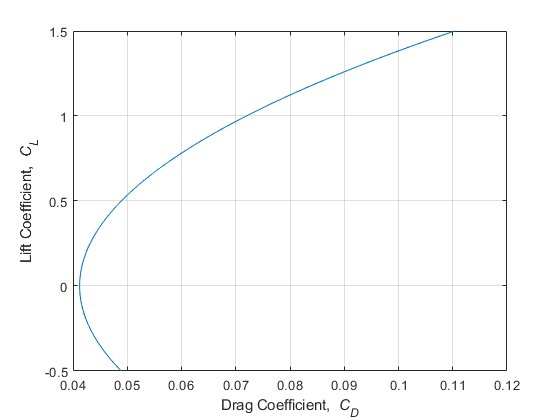


plot (CD,CL)
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on


LDMax

LDMax = 14.0490